# Superficies 3D

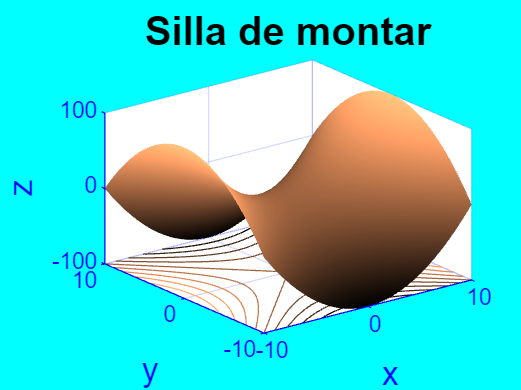

[x,y]=meshgrid(-10:0.1:10);
z=x.^2-y.^2;
surfc(x,y,z);
colormap copper
shading interp
title('Silla de montar','FontSize',16);
xlabel('x','FontSize',13);
ylabel('y','FontSize',13);
zlabel('z','FontSize',13);
set(gca,'color','white'); % color del fondo
set(gcf,'color','cyan');
ax = gca;
ax.XColor='b';
ax.YColor='b';
ax.ZColor='b';

Con funciones anónimas

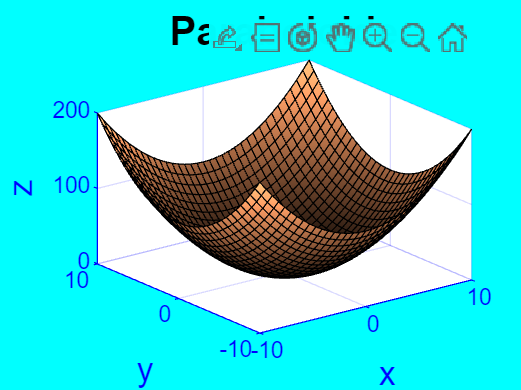

z=@(x,y)x.^2+y.^2;
fsurf(z,[-10 10]);
colormap copper
shading interp
title('Paraboloide','FontSize',16);
xlabel('x','FontSize',13);
ylabel('y','FontSize',13);
zlabel('z','FontSize',13);
set(gca,'color','white'); % color del fondo
set(gcf,'color','cyan');
ax = gca;
ax.XColor='b';
ax.YColor='b';
ax.ZColor='b';

# Superficies implicitas

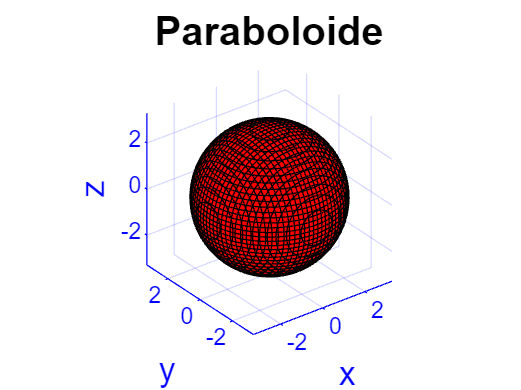

f=@(x,y,z)x.^2+y.^2+z.^2-9;
fimplicit3(f,[-10 10],'r')
shading interp
title('Paraboloide','FontSize',16);
xlabel('x','FontSize',13);
ylabel('y','FontSize',13);
zlabel('z','FontSize',13);
set(gca,'color','white'); % color del fondo
set(gcf,'color','w');
axis square
ax = gca;
ax.XColor='b';
ax.YColor='b';
ax.ZColor='b';

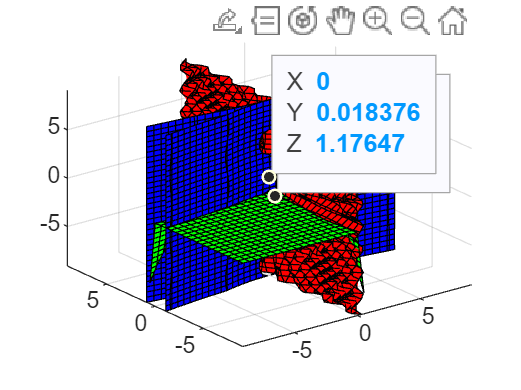

f=@(x,y,z)3*x-cos(y.*z)-1/2;
g=@(x,y,z)x.^2-81*(y+0.1).^2+sin(z)+1.06;
h=@(x,y,z)exp(-x.*y)+20*z+(10*pi-3)/3;
fimplicit3(f,[-10 10],'r')
hold on
fimplicit3(g,[-10 10],'b')
fimplicit3(h,[-10 10],'g')
hold off

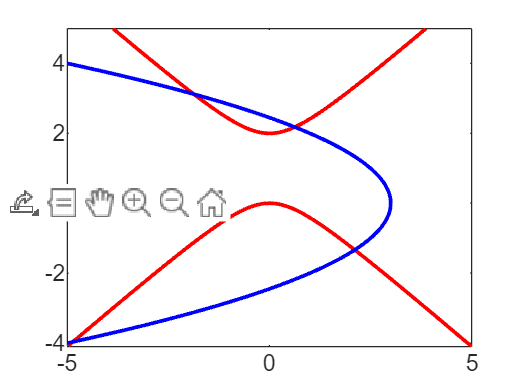

f=@(x1,x2)x1.^2-x2.^2+2*x2;
g=@(x1,x2)2*x1+x2.^2-6;
fimplicit(f,'r','LineWidth',1.5)
hold on
fimplicit(g,'b','LineWidth',1.5)
hold off

R=0.08206;
a=1.39;
b=0.03913;
n=1.5;
P=@(V,T)(n.*R.*T)./(V-b)-(n.^2.*a)./V.^2;
fsurf(P,[0.3 1.2 273 473]);
P(1,300)

ans = 35.3033

colormap winter

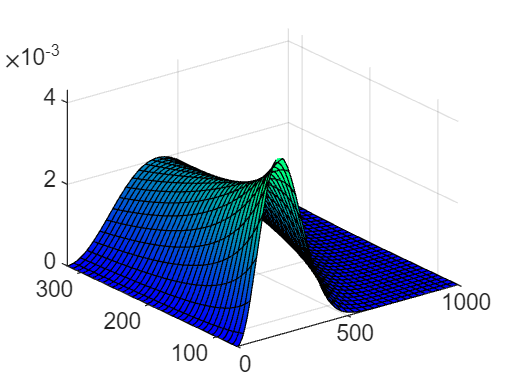

R=8.31;
M=0.032;
P=@(v,T)4*pi*(M./(2*pi*R*T)).^(3/2).*v.^2.*exp((-M*v.^2)./(2*R*T));
fsurf(P,[0 1000 70 320])
colormap winter